# Southern Highlands Aquifer

clear

## Basic Mars Topography

The topography of mars was measured by the [Mars Laser Orbiter Altimeter](https://attic.gsfc.nasa.gov/mola/) (MOLA) and reported by Smith et al. (1999). Their topographic map of Mars is shown below. ﻿The most prominent feature on the surface of Mars is the near-hemispheric dichotomy between the **southern highlands** and **northern lowlands**. ﻿The northern lowlands cover approximately 1/3 of the surface and have an average elevation approximately 5 km lower than the cratered southern highlands. This dichotomy may have formed  by a large oblique impact early in Mars history (Andrews-Hanna et al. 2008). 

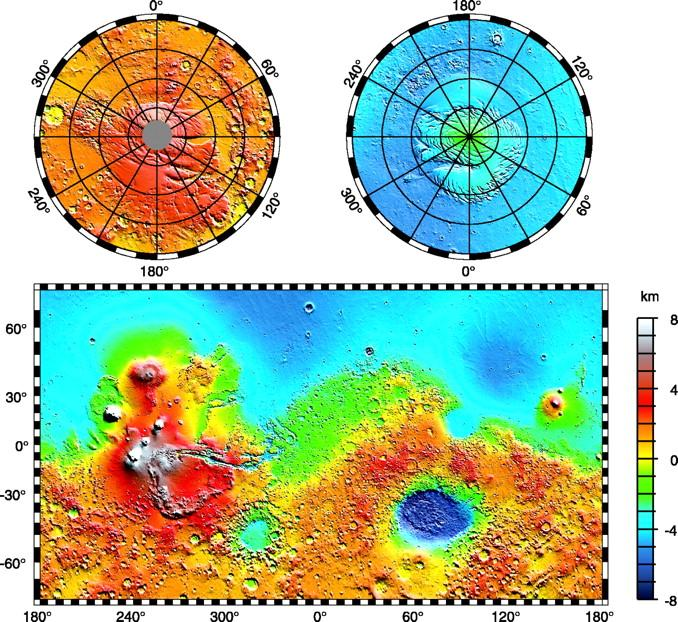

Various lines of evidence indicate that early Mars had a hydrologic cycle with both surface and groundwater activity in the southern highlands (Ehlman et al. 2011) and possibly an ocean in the northern lowlands (Parker et al. 1993). ﻿﻿Currently model for an early Mars with a warm, wet subsurface and an icy, arid surface is most plusible.

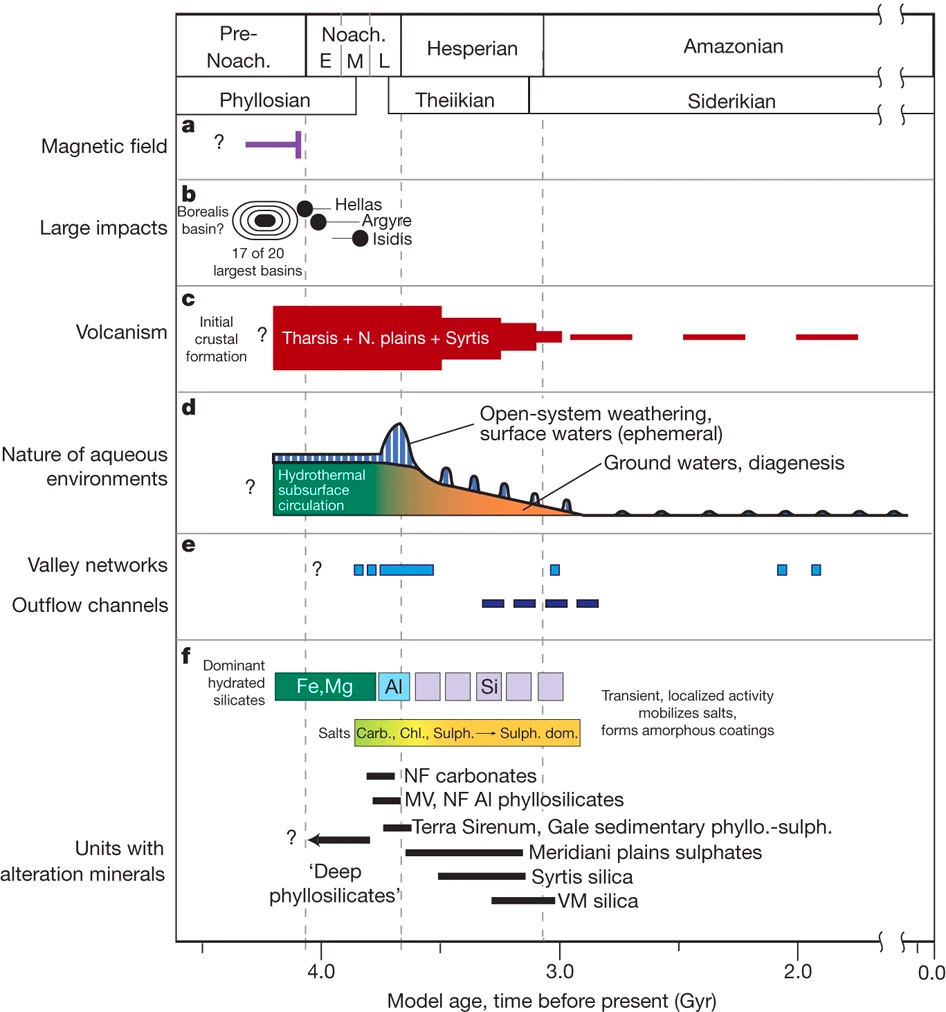

The global groundwater flow would have been driven primarily by precipitation-induced recharge and evaporative loss. The image below show a cross-section across the dichotomy boundary including the deep aquifer beneath the highlands  (Michalski et al. 2013). 

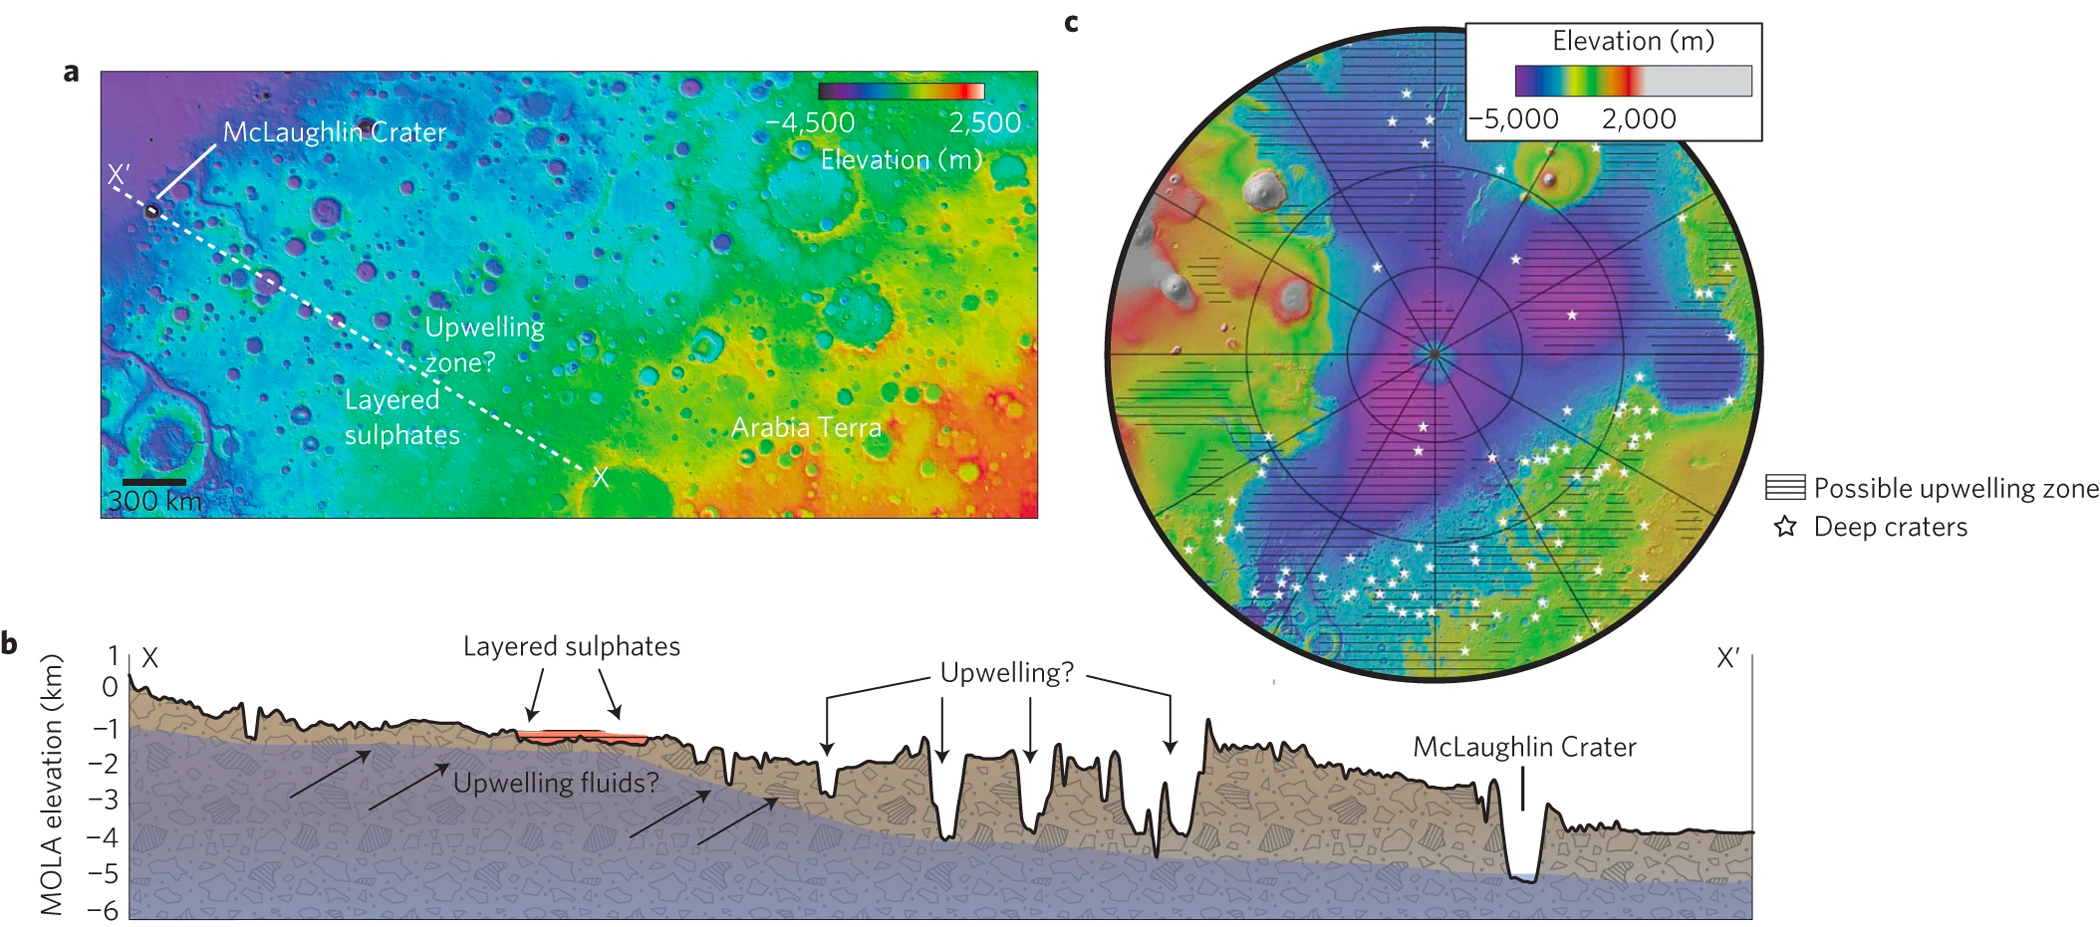

Note that the horizonal dimension here is more than 1000 km! This aquifer is though to span the entire southern highlands. It can eithe be *unconfined* as shown in the illustration shown above, or it could be *confined* by a thick layer of permeafrost. We will consider both cases, but state with the confined aquifer because the governing equation is linear.

## Spherical cap approximation of dichotomy

R = 3389508; % [m] Mars' mean radius 
grav = 3.711;   % [m/s^2] grav. acceleration on Mars

The southern highlands comprise approximately 2/3 of the Martian surface. The mean lattitude of the the dichotomy boundary between the southern highlands and the northern lowlands can be computed from using the formula for the area of a spherical shell. The variable are defined in the figure below, where $r$ is the radius of the sphere and $\theta$ is the co-latitude.

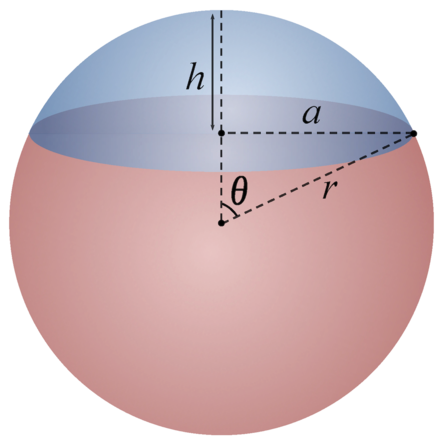

The area of the sphere is $A_{sph} =4\pi r^2$ and the area of a sphericl cap is $A_{cap}=2\pi r^2(1-\cos\theta)$, so that we have the ratio

$\frac{A_{cap}}{A_{sph}} = \frac{1}{2}(1-\cos\theta)$  so that the co-lattitude of the dichotomy boundry is $\theta_{bnd} = \arccos (1/3) \approx 1.23$ ($70.5 ^\circ$).

theta_bnd = acos(1/3);
theta_bnd_deg = rad2deg(theta_bnd)

theta_bnd_deg = 70.5288

lattitude_bnd = 90-theta_bnd_deg;
A_tot = 4*pi*R^2; % [m^2] Mars' surface area
A_high = 2*pi*R^2*(1-cos(pi-theta_bnd));
A_low  = 2*pi*R^2*(1-cos(theta_bnd));
A_low/(1e3)^2

ans = 4.8124e+07

This calculation gives an area of $48\cdot10^6$ km$^2$ for the northen lowlands, which is comparable to the $46\cdot10^6$ km$^2$cited by Parker et al. (1993). 

Hence the distance from the south pole to the dichotomy boundary is


$$l = (\pi-\theta_{bnd}) r^2$$


half_arc_high = R*(pi-theta_bnd)    % distance from south pole to dichotomy bnd

half_arc_high = 6.4761e+06

half_arc_low = R*theta_bnd;         % distance from the north pole to the dichotomy bnd

so that the distance from the south pole to the dichotomy boundary is $6.5\cdot10^3$ km. This will the length of our model domain. In contrast, the thickness of the aquifer is at most 10 km, leading to an extreme aspect ratio that allows us to reduce the dimensionality of the problem by vertically integrating the governing equation.

## Example Problem 1: Confined linear aquifer model

### Governing equation and BC's

Initially we neglect the spherical cap geometry and simply assume a linear domain (for now!). A steady confined groundwater aquifer across the entire southern highlands leads following governing equations

$-\frac{\mathrm{d}}{\mathrm{d}x}\left[bK\frac{\mathrm{d}h}{\mathrm{d}x}\right] = f_s$ for $x\in\left[0,\,l\right]$,

where $b$ is the thickness of the aquifer and $f_s$ is the precipitation. The boundary conditions are given by:

- $\left.\frac{\mathrm{d}h}{\mathrm{d}x}\right|_0=0$ - due to the symmetry at the south pole

- $h(x=l) = h_o$ - ocean level at dichotomy

### Model parameters

Of course all model paramters are highly uncertain, so that we have to explore the solution for  range paramter values. Below we collect values from the literature that provide a first start.

#### Aquifer length

Hence the distance from the south pole to the dichotomy boundary is


$$l = (\pi-\theta_{bnd}) r^2$$


l = R*(pi-theta_bnd)    % distance from south pole to dichotomy bnd

l = 6.4761e+06

so that the distance from the south pole to the dichotomy boundary is $6.5\cdot10^3$ km. This will the length of our model domain. In contrast, the thickness of the aquifer is at most 10 km, leading to an extreme aspect ratio that allows us to reduce the dimensionality of the problem by vertically integrating the governing equation.

#### Precipitation

Andrews-Hanna and Lewis (2011) used comparison between global groundwater models to observed sedimentary deposits to estimate a mean equatorial precipitation rate 0.13 mm/yr in the early and middle Noachian. So this is the value we will assume for now.

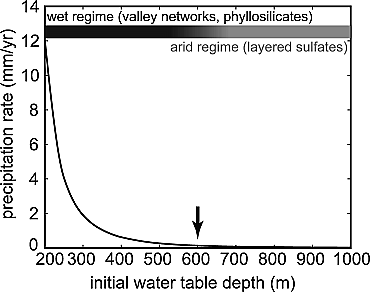

yr2s = 60^2*24*365.25; % seconds per year
fp = 0.13; % [mm/yr] mean precipitation
fs = fp/1e3/yr2s

fs = 4.1195e-12

#### Hydraulic conductivity

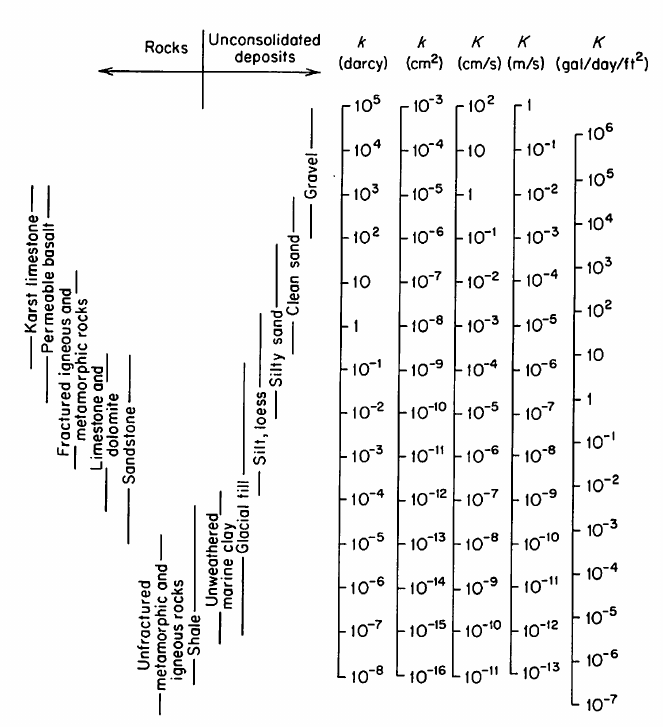

Our governing equation is in terms of the hydraulic conductivity, $K$, commonly used in groundwater hydrology on Earth. However, $K$ is not an intrinsic property of rocks, instead it is a combination of paramters


$$K = \frac{k\rho g}{\mu}$$


where $k$ is the intrinsic permeability of the rock, $\rho$ is the density of water, $g$ is the graviatiaional acceleration on Mars, and $\mu$ is the viscosity of the water. 

rho = 1e3;          % [kg/m^3] density of water 
grav = 3.711;       % [m/s^2] grav. acceleration on Mars
k = 1e-11;          % [m^2] permeability (Hanna & Phillips 2005)
mu = 1e-3;          % [Pa s] water viscosity
K = k*rho*grav/mu   % [m/s] hydraulic conductivity

K = 3.7110e-05

#### Aquifer thickness

Various authors have estimated the thickness of the aquifer between 3 and 5 km. Here we choose 5 km

b = 5e3; % [m] aquifer thickness

#### Sea level in the northern highlands

﻿The northern lowlands has been interpreted to have hosted a groundwater‐fed ocean in the Noachian, when temperatures were much warmer than present‐day (e.g., Clifford & Parker, 2001; Parker et al., 1989; Parker et al., 1993). ﻿

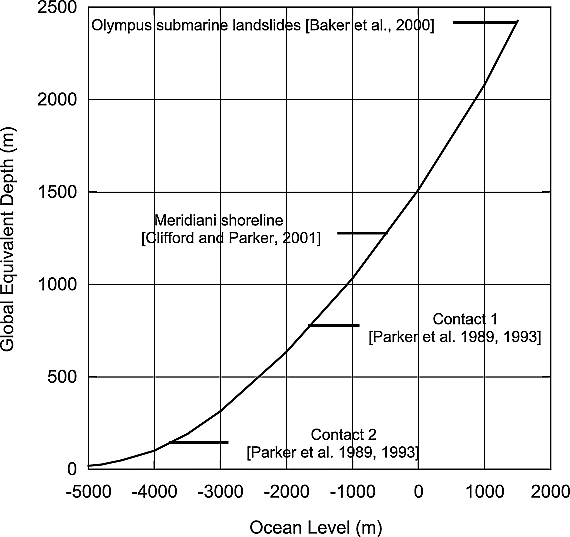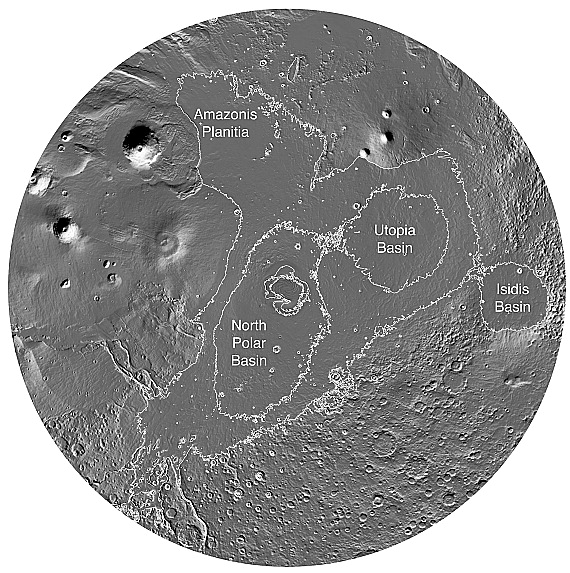

The figure above from Carr and Head (2003) shows that there is a wide range in estimated shorelines of the ocean in the northern lowlands. For now let's pick the Meridiani shoreline from Clifford and Parker (2001) that seems to most obviously follow the Dichotomy boundry.

ho = -500; % [m]

### Analytic solution

The analytic solution to the above problem is given by


$$h(x)=h_o + \frac{f_s\,l^2}{2bK}\left(1-\left(\frac{x}{l}\right)^2\right)$$


showing that the increase of the head at the south pole over sea level is $\Delta h = h(0)-h_o=\frac{f_s\,l^2}{2bK}\approx 465$ m.

Dh = (fs*l^2)/(2*b*K)

Dh = 465.5608

## References:

- [Smith et al. (1999) The Global Topography of Mars and Implications for Surface Evolution, Science 284(5419), ﻿1495-1503](https://science.sciencemag.org/content/284/5419/1495)

- [Andrews-Hanna et al. (2008) The Borealis basin and the origin of the martian crustal dichotomy, Nature, ﻿453(﻿7199), ﻿1212-1215](https://www.nature.com/articles/nature07011)

- [Ehlmann et al. (2011) Subsurface water and clay mineral formation during the early history of Mars, Nature, 479(7371), 53-60](https://www.nature.com/articles/nature10582)

- [Parker et al. (1993) Coastal geomorphology of the Martian northern plains, J. Geophys Res., 98(E6), ﻿11061-11078](https://agupubs.onlinelibrary.wiley.com/doi/10.1029/93JE00618)

- [Michalski et al. (2013) Groundwater activity on Mars and implications for a deep biosphere, Nature Geoscience, 6(2), 133-138](https://www.nature.com/articles/ngeo1706)

- [Clifford and Parker (2001) The Evolution of the Martian Hydrosphere: Implications for the Fate of a Primordial Ocean and the Current State of the Northern Plains, Icarus, 154(1), 40-79](https://doi.org/10.1006/icar.2001.6671)

- [Carr and Head (2003) Oceans on Mars: An assessment of the observational evidence and possible fate, J. Geophys Res. E - Planets, (108)5, 1-28](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2002JE001963)

- [Andrews-Hanna and Lewis (2011) Early Mars hydrology: 2. Hydrological evolution in the Noachian and Hesperian epochs, J. Geophys. Res. E: Planets, 116(2), 1-20](https://agupubs.onlinelibrary.wiley.com/doi/10.1029/2010JE003709)